# Symbolic variables definitions

clc;   clear;   close all ;
ref = CoolPropPyWrapper('HEOS::R134a');

CoolProp version: 6.4.1


% Load all symbolic variables
symbolicVariables

% Load hi-fi model data for operating point extraction
load('HiFi_model_data.mat')			


% ===============================================================================================================
%                                 steady state variables
% ===============================================================================================================

% ========================= Temperatures =========================
% NOT USED
% ------------------------------
%T1															% [K] defined in constraints from T7
%T3															% [K] defined in constraints from T2 
%T4															% [K] Not defined from Condenser, never used
%T5															% [K] Not defined from Condenser Throttle valve, never used

% Operating points
T2			= 273.15 + out.logsout{28}.Values.Data(end,3);	% [K] - used in lookup
T6			= 273.15 + out.logsout{13}.Values.Data(end,3);	% [K] - ONLY used in lookup
T7			= 273.15 + out.logsout{26}.Values.Data(end,3);	% [K] - used in lookup


% ========================= Pressures =========================

% Operating points
p1        	= out.logsout{28}.Values.Data(end,1) * 1e5 ;	% [Pa] bar to pascal, 10^5 - used in lookup that is never used
p2			= out.logsout{25}.Values.Data(end,1) * 1e5 ;	% [Pa] defined in constraints
p3        	= out.logsout{3}.Values.Data(end,1)	 * 1e5 ;	% [Pa] 
p4          = out.logsout{13}.Values.Data(end,1) * 1e5 ;	% [Pa] 

% Table lookup, later linearised and used as constraint eq.
p5        	= out.logsout{26}.Values.Data(end,1) * 1e5 ;	% [Pa] - used in lookup

% ======================= Enthalpies =========================
% NOT USED
% ------------------------------
% h1														% a lookup, but never used (b.c. h2 is never used)
% h2														% defined in constraints, but never used
% h4														% defined in constraints, but never used
% h7         = ref.HTP(T7 - 273.15 , p5*1e-5);				% never used AT ALL

% Table lookups
%h3															% 
%h5         												% 
%h6         												% HTP uses p in bar.. DOES NOT ALIGN WITH: out.logsout{13}.Values.Data(end,2) 
%h_dew      												% average of pressure before and after evaporator


% ========================= Compressor =========================
V_1_COM1   	= 50e-6;										% 50 cm^3 - found in krestens guestimate?
V_1_COM2   	= V_1_COM1/2;									% 2nd stage is half the first
V_C_COM1   	= V_1_COM1*0.05;								% 5pct of pre stroke volume
V_C_COM2   	= V_1_COM2*0.05;								% 5pct of pre stroke volume
% gamma		= 1.2;											% freon r134a side 31 T=20 p=500kPa
kl_1       	= 1/2200;										% found in compressor script sent from kresten
kl_2       	= 1/2200;										% found in compressor script sent from kresten 

gammaT1 = (out.logsout{28}.Values.Data(end,3) + out.logsout{26}.Values.Data(end,3)) /2;
gammaP1 = (out.logsout{28}.Values.Data(end,1) + out.logsout{26}.Values.Data(end,1)) /2;
gammaT2 = (out.logsout{28}.Values.Data(end,3) + out.logsout{25}.Values.Data(end,3)) /2;
gammaP2 = (out.logsout{28}.Values.Data(end,1) + out.logsout{25}.Values.Data(end,1)) /2;

gamma1     = ref.CpRatioTP(gammaT1, gammaP1); %T=(22-5)/2 degC    p=(1.9+4.5)/2 bar,   see also freom r134a side 25
gamma2     = ref.CpRatioTP(gammaT2, gammaP2); %T=(48+22)/2 degC    p=(4.5+7.7)/2 bar,   see also freom r134a side 34



% Table lookups
% v_1_COM1													% p is from p_i1_COM1 - specific volume compressor in 
% v_1_COM2													% p is from p_i1_COM2 - Lookuptable defined below    


% ========================= Condenser =========================
UA_ma		= 650;											% found kresten PHD
UA_rm		= 1500;											% found kresten PHD
lambda		= 0.1;											% pressure drop constant, found in krestens sim model
Cp_m		= 387;											% evaporator and condeser metal (copper), kresten approve
M_m_Con		= 22.976;										% found in ??? (coefficient sheet?

% Operating point
T_r			= 30 + 273.15;									% found in ???


% ========================= Evaporator =========================
UA_1      	= 3510;											% found in krestens phd
UA_2      	= 1930;											% found in krestens phd
UA_3      	= 50;											% found in krestens phd
V_i_Eva		= 11.9*0.001;									% is 11.9 L  - L->m3 ; from simulink->14*1.8*6*(0.005^2)*pi; %nr_pipes*length*area
Cp_air    	= 1003.5;										% heat capacity of air, google
rho_air		= 1.225;										% density of air
M_m_Eva		= 30;											% [kg] found coeff sheet - evaporator metal mass

% Table lookups
% T_lv
% v_Eva

% Operating points
T_ret     	= out.logsout{15}.Values.Data(end,1);			% found in sim - return temperature % does not come out in celcius as opposed to other temperatures..


% ========================= Cargo =========================
M_air     	= (13.4*2.35*2.46)*rho_air;						% [kg] mass of air in box - H * L * B * air density
M_cargo   	= 1000;											% [kg] found in sim
Cp_cargo  	= 447;											% found in sim
UA_cargo  	= 20;											% found in sim


% ========================= Valve =========================
C_Val   	= 0.64;											% discharge coefficient
A_Val   	= ((20/2)^2)*pi*10^-6;							% Cross sectional area
% K_Val   	= C_Val*A_Val;									% collected constant
K_Val		= 1e-5;											% approximate value from krestens phd

% Condenser Throttle Valve
% ------------------------------
% Operating points
v_CTV_in	= 0.0008;										% found ???

% Expansion Valve
% ------------------------------
% Operating points
v_EV_in         = 0.01;										% found ???

% ========================= Box =========================
UA_ba      	= 25;    
UA_amb     	= 25;
Cp_box     	= 447;
M_box      	= 1000;
	

% ===============================================================================================================
%                  Operating points: inputs, states, disturbances                        
% ===============================================================================================================

% ========================= inputs =========================
omega_op   = 28;			% [Hz]
Theta_1_op = 19.5	/ 100;	% [%]
Theta_2_op = 12.2	/ 100;	% [%]
U_fan_1_op = 1500;			% [rpm] - 1600 is around half speed
U_fan_2_op = 1500;			% [rpm] - 1600 is around half speed
T_ambi_op = 273.15 + 20;			% [K]


% ========================= states =========================
M_PJJ_OP       = 0.001 * (1/0.0481); % m^3 * 1/specificVolume
% M_PJJ_OP       = 0.001 * (1/out.logsout{28}.Values.Data(end,6));
M_Con_OP       = 1;
T_m_OP         = 35 + 273.15;
% T_m_OP         = ref.TDewP(p3) + 5;
m_dot_air_OP   = 1;     
T_mlv_OP       = -5 + 273.15; 
T_mv_OP        = -5 + 273.15;
M_lv_OP        = 1;
M_v_OP         = 1;
T_air_OP       = 5 + 273.15; 
T_box_OP       = 20 + 273.15; 
T_cargo_OP     = 267.9;   



# Table lookups

% Placeholder table lookup functions
syms tUpsilon tN tM tGamma tPI
UpsilonLookup	= @(T, p)	tUpsilon*T*p;
Nlookup			= @(p)		tN*p;
Mlookup			= @(p)		tM*p;
Gammalookup		= @(T, p)	tGamma*T*p;
PIlookup		= @(h, p)	tPI*h*p;


% h3				= UpsilonLookup(T3, p2);				% COM2
% h3				= ref.HTP(T3,p2)
h3				= out.logsout{25}.Values.Data(end,2);
% h5				= Nlookup(p1);							% FT - dew/bub point
h5				= out.logsout{21}.Values.Data(end,2);	% supposed to be table lookup

% h6				= Mlookup(p1);							% FT - dew/bub point
h6         	= ref.HTP(T6 - 273.15, p4*1e-5);		% HTP uses p in bar.. DOES NOT ALIGN WITH: out.logsout{13}.Values.Data(end,2) 

% v_1_COM1		= Gammalookup(T7, p_i1_COM1);			% COM1
v_1_COM1		= 0.1234;								% ref.VTP(T3,1.9 - 4.5455e-04*omega_op) 
% v_1_COM2		= Gammalookup(T2, p_i1_COM2);			% COM2
v_1_COM2		= 7.61e-4;	
% p5				= PIlookup(h_7, (V_i_Eva-V_lv)/M_v);	% Eva - 
p5				= out.logsout{26}.Values.Data(end,1) * 1e5 ;	% [Pa] - used in lookup


% "non-official" - These are not mathematically defined as lookups in phd but are lookups anyway
% ------------------------------
v_Eva			= ref.VPX(p5*1e-5, 0.1);				% Eva - old value: 0.05; - v_l refrigerant specific volume Xe = 0.1
T_lv			= ref.TBubP(1.9) + 273.15;				% Eva - ref.TBubP(1.9) / ref.TDewP(1.9) => same
h_dew      	    = ref.HDewP( (p4*1e-5 + p5*1e-5) / 2);	% Eva

% Never used
% ------------------------------
% h1			= Upsilonlookup(T1, p1)					% COM1  (never used b.c. h2 is never used)

# Other functions to be defined

% ===========================================================
% linearisation of table look up for p5
delta_X = 0.0001;
hv_op = 392030;
Vi_op = 0.0119;
Vl_op = 0.011;
M_v_linPoint = 0.0085; 
linearOffset_p5 = ref.PHD(hv_op, M_v_linPoint/(Vi_op-Vl_op));                        % Calculate f(p0) and f'(p0)
linearSlope_p5 = (ref.PHD(hv_op, (M_v_linPoint+delta_X)/(Vi_op-Vl_op)) - ...
	ref.PHD(hv_op, (M_v_linPoint-delta_X)/(Vi_op-Vl_op)) ) / (2*delta_X);



# Constraint equations definitions

% ====================================================================================================================================
% Sorted constraints
% ====================================================================================================================================

% Table lookup
p5              =       100000 * (linearOffset_p5 + linearSlope_p5 * (M_v - M_v_linPoint));

% Other
p_i1_COM1		= 		p5 - kl_1*omega  													;	% COM1								
p_i2_COM1		= 		p1 + kl_2*omega  													;	% COM1
T1				= 		T7*(p1/p5)^((gamma1-1)/gamma1)        								;	% COM1	
v_2_COM1		= 		(p_i2_COM1/p_i1_COM1)^(-1 /gamma1) 	 								;	% COM1	
m_dot_1			= 		(V_1_COM1/v_1_COM1 - V_C_COM1/v_2_COM1)*omega/2 	 				;	% COM1	
p_i1_COM2		= 		p1 - kl_1*omega  													;	% COM2								
p_i2_COM2		= 		p2 + kl_2*omega 	 												;	% COM2	
v_2_COM2		= 		(p_i2_COM2/p_i1_COM2)^(-1 /gamma2)  								;	% COM2	
Q_rm			= 		UA_rm * (T_r - T_m)  												;	% Con	
m_dot_2_COM2	=		(V_1_COM2/v_1_COM2 - V_C_COM2/v_2_COM2)*omega/2 	 				;	% COM2	
h4				= 		h3 - Q_rm/m_dot_2_COM2 		 										;	% Con	
m_dot_3_Val		=		Theta_2*K_Val*sqrt((1/v_CTV_in) * (p3-p1)) 		 				;	% Val
m_dot_5_Val		=		Theta_1*K_Val*sqrt((1/v_EV_in) * (p1-p4)) 	 					;	% Val
m_dot_4			= 		(m_dot_3_Val*h4 - m_dot_5_Val*h6)/h5 		 						;	% FT	
h2				= 		(h1* m_dot_1 + h5*m_dot_4)/m_dot_2_COM2 	 						;	% PJJ
% m_dot_2_PJJ		= 		m_dot_1 + m_dot_4 								 				;	% PJJ	- unused
T3				= 		T2*(p2/p1)^((gamma2-1)/gamma2)  	        						;	% COM2	
p2				= 		p3 - lambda*m_dot_2_COM2 *100000	 								;	% Con
%m_dot_3_Con		= 		m_dot_2_COM2 + M_Con - V_i_Con/v_Con 	 						;	% Con	- unused
Q_ma			= 		UA_ma*(T_m - T_ambi)*(0.05 + U_fan_1/1530)  						;	% Con	
% m_dot_5			= 		m_dot_3_Val - m_dot_4 					 						;	% FT	- unused
sigma			= 		(M_lv*v_Eva)/V_i_Eva 					 							;	% Eva
V_lv			=		V_i_Eva * sigma														;	% Eva
U_star_p		= 		((U_fan_2/3060)*100-55.56)*0.0335 		 							;	% Eva	
Q_fan_2			=		177.76 + 223.95*U_star_p + 105.85*U_star_p^2 + 16.75*U_star_p^3 	; 	% Eva	
T_retfan		=		T_ret + Q_fan_2/(m_dot_air*Cp_air) 		        					;	% Eva	
Q_amv			=		Cp_air*m_dot_air*(T_retfan-T_mv) 			 						;	% Eva	
T_retsh			=		T_retfan - Q_amv/(m_dot_air*Cp_air) 	        					;	% Eva	
Q_amlv			= 		Cp_air*m_dot_air*(T_retsh-T_mlv) 					 				;	% Eva
U_star_m_dot	= 		(U_fan_2 - 2270.4)*0.0017 						 					;	% Eva
V_bar_dot_air	= 		0.7273 + 0.1202*U_star_m_dot - 0.0044*U_star_m_dot^2 		 		;	% Eva
m_bar_dot_air	= 		V_bar_dot_air*rho_air 						 						;	% Eva
Q_mvmlv			= 		UA_3*(T_mv-T_mlv) 							 						;	% Eva	
Q_mlv			= 		UA_1*(T_mlv-T_lv)*sigma 						 					;	% Eva	
Q_mv			= 		UA_2*(T_mv-T7)*(1-sigma) 					 						;	% Eva		
h_lv			= 		h6 + Q_mlv/m_dot_5_Val 							 					;	% Eva	
m_dot_dew		= 		Q_mlv/(h_dew-h6) 								 					;	% Eva		

h_7				= 		h_dew + Q_mv/ m_dot_dew 							 				;	% Eva	

T_sup			=		T_retfan + (Q_amlv + Q_amv)/(Cp_air * m_dot_air)  	        		;	% Eva																																						
																									

Q_cool          =       Cp_air*m_dot_air *(T_ret - T_sup)                                   ;   % Box
Q_amb           =       (T_ambi - T_box) * UA_amb                                           ;   % Box
Q_ba            =       (T_box - T_air) * UA_ba                                             ;   % Box
Q_ca            =       (T_cargo - T_air) * UA_cargo                                        ;   % Box


% ====================================================================================================================================
% State equations 
% ====================================================================================================================================		

M_PJJ_dot		= m_dot_1 + m_dot_4 - m_dot_2_COM2;
M_Con_dot		= m_dot_2_COM2 - m_dot_3_Val;
T_m_dot			= (Q_rm - Q_ma)/(M_m_Con * Cp_m);
m_dot_air_dot	= (m_bar_dot_air - m_dot_air)/10;
T_mlv_dot		= (Q_amlv - Q_mlv + Q_mvmlv)/(M_m_Eva * sigma * Cp_m);
T_mv_dot		= (Q_amv - Q_mv - Q_mvmlv)/(M_m_Eva * (1- sigma) * Cp_m);
M_lv_dot	    = m_dot_5_Val -  m_dot_dew;
M_v_dot			=  m_dot_dew - m_dot_1;
T_air_dot       = (Q_ca + Q_ba + Q_fan_2 - Q_cool ) / (M_air + Cp_air);
T_box_dot       = (Q_amb - Q_ba ) / (M_box * Cp_box);
T_cargo_dot     = -Q_ca / (M_cargo * Cp_cargo);


f(1,1)  = M_PJJ_dot;
f(2,1)  = M_Con_dot;
f(3,1)  = T_m_dot;
f(4,1)  = m_dot_air_dot;
f(5,1)  = T_mlv_dot;
f(6,1)  = T_mv_dot;
f(7,1)  = M_lv_dot;
f(8,1)  = M_v_dot;
f(9,1)  = T_air_dot;
f(10,1) = T_box_dot;
f(11,1) = T_cargo_dot;

f

## Simulation

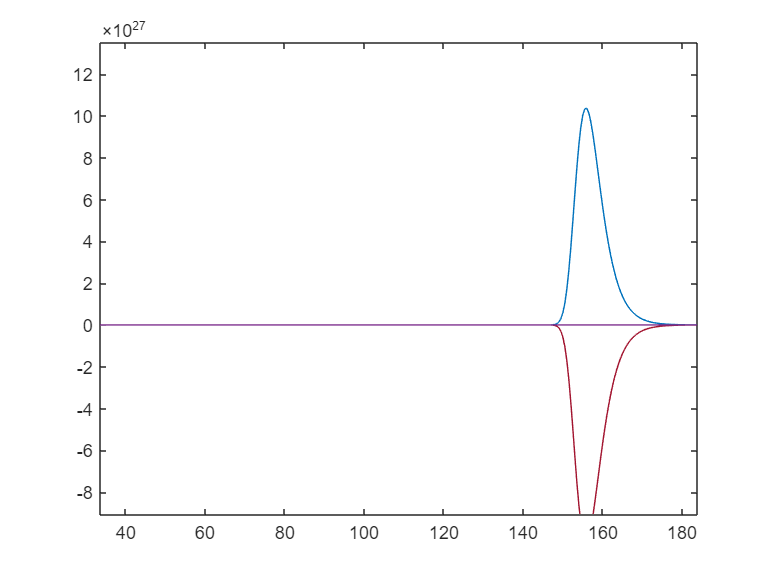

Time = 100;
Ts = 0.1;
no_samples = Time/Ts;
Time_vector = 0:Ts:Time-Ts;

f=[M_PJJ_dot;
   M_Con_dot;
   T_m_dot;
   m_dot_air_dot;
   T_mlv_dot;
   T_mv_dot;
   M_lv_dot;
   M_v_dot;
   T_air_dot;
   T_box_dot;
   T_cargo_dot];

% ================================================================= initial conditions
state_Variables = [M_PJJ; M_Con; T_m; m_dot_air; T_mlv; T_mv; M_lv; M_v; T_air;  T_box;  T_cargo];
init_conditions = [0.001; 1;     302; 0.25;      273;   273;  1;    0;   273+10; 273+10; 273+10];

Input_OP_parameters = [U_fan_1, U_fan_2, Theta_1, Theta_2, omega, T_ambi];
% Input_OP_values = [U_fan_1_op, U_fan_2_op, Theta_2_op, omega_op, T_ambi_OP];
zero_input = 10e-100;
Input_OP_values = [0,0,0,0,zero_input,0];

f = subs(f, Input_OP_parameters, Input_OP_values);

clear states state_derivatives
states(:,1) = init_conditions;

state_derivatives(:,1) = subs(f,state_Variables,states(:,1));

for i=2:no_samples

states(:,i) = states(:,i-1) + double(state_derivatives(:,i-1))*Ts;
state_derivatives(:,i) = subs(f,state_Variables,states(:,i));
end

figure(2)
plot(Time_vector,state_derivatives(:,:)')

# Temporary Table shit

% h3 = ref.HTP(T3,p2)										% Contains omega (state) from p2
% h5				= ref.HDewP(p1);						% just an OP
% h6				= ref.HTP(T6 - 273.15, p4*1e-5);		% Just an OP
% v_1_COM1		= Gammalookup(T7, p_i1_COM1);			% contains omega (state) from p_i1_COM1
% v_1_COM2		= Gammalookup(T2, p_i1_COM2);			% contains omega (state) from p_i1_COM2
% p5				= PIlookup(h_7, (V_i_Eva-V_lv)/M_v);	% contains M_lv, T_mv, T_mlv (states) from h_7

% "non-official" - These are not mathematically defined as lookups in phd but are lookups anyway
% ------------------------------
% v_Eva			= ref.VPX(p5*1e-5, 0.1);				
% T_lv			= ref.TBubP(1.9) + 273.15;				
% h_dew      	    = ref.HDewP( (p4*1e-5 + p5*1e-5) / 2);	
% Never use
% -----------------------------
% h1			= Upsilonlookup(T1, p1)					

# Simulation of non linear system

% Time = 0.1;
% Ts = 0.01;
% t = 0:Ts:Time-Ts;
% no_samples = Time/Ts;
% 
% 
% % ================================================================== initial conditions ==================================================================
% state_Variables			= [M_PJJ;	M_Con;	T_m;   m_dot_air;  T_mlv;   T_mv;  M_lv;  M_v;    T_air;     T_box;     T_cargo];
% init_conditions			= [0.001;	2;		302;   1;          273;     273;   2;     0.0085;  273+10;    273+10;    273+10];
% 
% Input_OP_parameters 	= [U_fan_1, U_fan_2, Theta_1, Theta_2, omega, T_ambi];
% Input_OP_values			= [U_fan_1_op, U_fan_2_op, Theta_1_op, Theta_2_op, omega_op, T_ambi_op];
% f						= subs(f, Input_OP_parameters, Input_OP_values);
% 
% states(:,1) = init_conditions;
% 
% 
% for i=2:no_samples
% 	
% 	f_current = subs(f,state_Variables,states(:,i-1));
% 	states(:,i) = states(:,i-1) + f_current*Ts;
% 
% end
% states;
% 
% 
% titls = ["M_{PJJ}", "M_{Con}", "T_m}", "m_{dot}_{air}", "T_{mlv}", "T_{mv}", "M_{lv}", "M_v", "T_{air}", "T_{box}", "T_{cargo}"]
% for j = 1:11
% 	figure(j)
% 	plot(t,states(j,:))
% 	title(titls(j))
% end

# Linearisation

% % A matrix
% A_matrix = jacobian(f,[M_PJJ, M_Con, T_m, m_dot_air, T_mlv, T_mv, M_lv, M_v, T_air, T_box, T_cargo]);
% 
% Operating_point_parameters= [M_PJJ,     M_Con,     T_m,     m_dot_air,      T_mlv,     T_mv,       M_lv,     M_v,      T_air,      T_box,      T_cargo,      U_fan_1,    U_fan_2,    Theta_1,    Theta_2,    omega,    T_ambi];
% Operating_point_values    = [M_PJJ_OP,  M_Con_OP,  T_m_OP,  m_dot_air_OP,   T_mlv_OP,  T_mv_OP,    M_lv_OP,  M_v_OP,   T_air_OP,   T_box_OP,   T_cargo_OP,   U_fan_1_op, U_fan_2_op, Theta_1_op, Theta_2_op, omega_op, T_ambi_op];
% 
% % A_matrix_lin = double(subs(A_matrix, Operating_point_parameters, Operating_point_values))

% % B matrix
% B_matrix = jacobian(f,[omega, Theta_1, Theta_2, U_fan_1, U_fan_2]);
% 
% % B_matrix_lin = double(subs(B_matrix, Operating_point_parameters, Operating_point_values))
% 

% % Bd matrix
% Bd_matrix = jacobian(f,[T_ambi]);
% Bd_matrix_lin = double(subs(Bd_matrix, Operating_point_parameters, Operating_point_values))

% % C matrix
% 
% C = [0 0 0 0 0 0 0 0 0 0 1]; %last state is cargo temp